# Programación Dinámica e Iteración de la Función Valor

# (El Modelo Neoclásico de Crecimiento)

Mauricio M. Tejada

ILADES - Universidad Alberto Hurtado

## El Problema de Optimización 

El problema de optimización del planificador central es el siguiente:


$$\begin{array}{rcl}
\max U_{0} & = & \sum_{t=0}^{\infty}\beta^{t}\ln c_{t}\\
s.a &  & c_{t}+i_{t}=Ak_{t}^{\alpha}\\
 &  & k_{t+1}=i_{t}\\
 &  & k_{0}\,dado.
\end{array}$$


Alternativamente:


$$\begin{array}{rcl}
\max U_{0} & = & \sum_{t=0}^{\infty}\beta^{t}\ln c_{t}\\
s.a &  & c_{t}+k_{t+1}=Ak_{t}^{\alpha}\\
 &  & k_{0}\,dado.
\end{array}$$


La ecuación de Bellman es:


$$v(k_{t})=\max_{k_{t+1}}\left\{ \log\left(Ak_{t}^{\alpha}-k_{t+1}\right)+\beta v(k_{t+1})\right\}$$


## Solución Algebraica

La solución del problema funcional está dada por la función valor y la función de política:


$$v(k_{k})\,\,y\,\,k_{t+1}=g(k_{t})$$


Conocemos la solución de este problema:


$$\begin{array}{rcl}
k_{t+1} & = & \frac{\beta F}{1+\beta F}Ak_{t}^{\alpha}\\
v(k_{t}) & = & E+F\ln(k_{t})
\end{array}$$


donde:


$$\begin{array}{rcl}
E & = & \frac{1}{1-\beta}\left[\ln\left(A\left(1-\alpha\beta\right)\right)+\frac{\alpha\beta}{1-\alpha\beta}\ln\left(Aa\beta\right)\right]\\
F & = & \frac{\alpha}{1-\alpha\beta}
\end{array}$$


La idea ahora es implementar la solución numérica en Julia y compararla con la obtenida algebraicamente.

## Implementación

Algoritmo:

- Definir un grid de puntos $k$ (discretización) y realizar una conjetura para $v\left(k\right)$ en cada posible punto del grid. 

- 2. Usando la conjetura evaluar el operador $Tv$ para cada punto en el grid (esto implica resolver el $\mathrm{max}\left\lbrace \cdot \;\right\rbrace \;$).

- 3. Evaluar si $v=Tv$ (usando algún grado de tolerancia), en tal caso terminar el proceso. Caso contrario volver al punto 2 usando la función valor resultante.

En términos de la ecuación de Bellman, la iteración sería:


$$v_{j+1}(k)=\max_{k'}\left\{ \ln\left(Ak^{\alpha}-k'\right)+\beta v_{j}(k')\right\}$$


Partir con algún $v_0 \left(k\right)$. 

% Discretizamos la variable de estado. Definimos primero el número de puntos en el grid de k
n = 50;

Parametros del modelo:

A     = 1;     % tecnologia
alpha = 0.36;  %  participacion del capital   
beta  = 0.9;   %  factor de descuento 

Definimos el grado de tolerancia de la iteración de la función valor y el porcentaje de la solución actual que será trasladado a la nueva conjetura:

crit = 1e-6;
step = 1;

Definimos el grid de puntos de $k$ como: $k_1,...,k_n \in [0.6k^*,1.4k^*]$

% Calcular kss y definir kgrid  
kss = (alpha*beta)^(1/(1-alpha)); % capital en EE
kgrid = kss * linspace(0.6, 1.4, n)';
%disp(kgrid);

Note que mientras más puntos tengamos en el grid, más precisión tendremos.

El siguiente paso es iterar la función valor partiendo de la siguiente conjetura:


$$v_{0}(k)=\left[\begin{array}{c}
0\\
\vdots \\
0
\end{array}\right]$$


% Definir valores inciales

val0 = zeros(n,1);  % Conjetura Inicial  
valiter = [];

Usamos interpolación vía splines (también podría usarse interpolación lineal, pero la aproximación es más imprecisa) para evaluar la función entre los puntos definidos en el grid del capital.

diff = 10;
opts=optimset('Diagnostics','off','Display','off');
flagdisp = 0; % 1 para mostrar las iteraciones

disp('Iterando');

Iterando


while diff>crit

    Tv = @(k, kf) log(A*k^alpha - kf) + beta*interp1(kgrid,val0,kf,'spline'); 
    val1 = zeros(n,1);  
    kdeci = zeros(n,1);
    
    for i = 1:n
        kdeci(i) = fminunc(@(x) -Tv(kgrid(i),x), kgrid(i), opts);
        val1(i) = Tv(kgrid(i), kdeci(i));
    end
    
    diff = abs(max(val1-val0));
    if flagdisp==1
        disp(diff);
    end
    valiter = [valiter val1];
    val0 = step*val1 + (1-step)*val0;
    
end
disp('Convergencia alcanzada!!');

Convergencia alcanzada!!


## Solución Algebraica

Para este problema particular conocemos la solución algebraica:

% Computar los coeficiente E y F (para compara la solucion con la que se % hallaria con lapiz y papel)
E1 = log(A*(1-alpha*beta));
E2 = alpha*beta/(1-alpha*beta) * log(A*alpha*beta); 
E = 1/(1-beta)*(E1 + E2);
F = alpha/(1-alpha*beta);

% Evaluar en la solucion algebraica la FV y la FP en kgrid
val_cs = E + F* log(kgrid);
kdeci_cs = beta*F/(1+beta*F)*A*kgrid.^alpha;

## Resultados Comparados

Función valor:

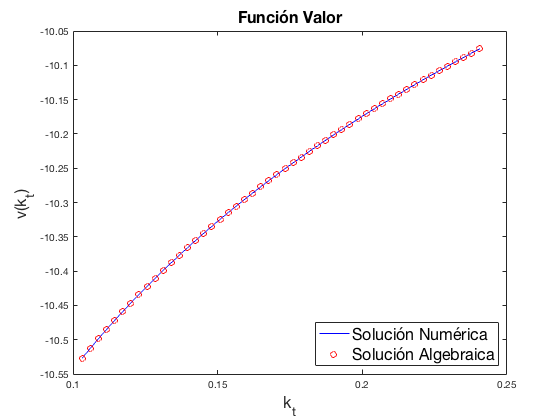

figure;
plot(kgrid,val0,'-b',kgrid,val_cs,'or');
title('Función Valor','fontsize',16);
ylabel('v(k_{t})','fontsize',16);
xlabel('k_{t}','fontsize',16);
legend({'Solución Numérica','Solución Algebraica'},'fontsize',16,'Location','southeast');

Función de política:

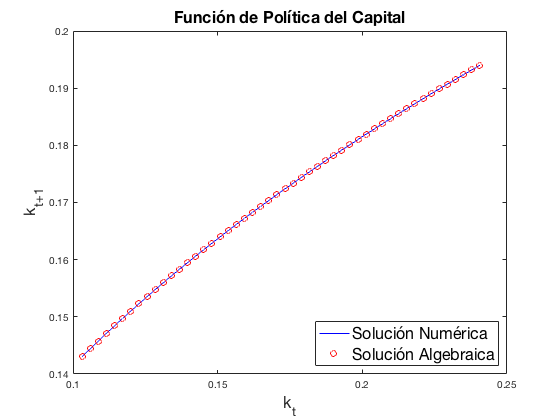

figure;
plot(kgrid,kdeci,'-b',kgrid,kdeci_cs,'or');
title('Función de Política del Capital','fontsize',16);
ylabel('k_{t+1}','fontsize',16);
xlabel('k_{t}','fontsize',16);
legend({'Solución Numérica','Solución Algebraica'},'fontsize',16,'Location','southeast');

Iteración de la función valor:

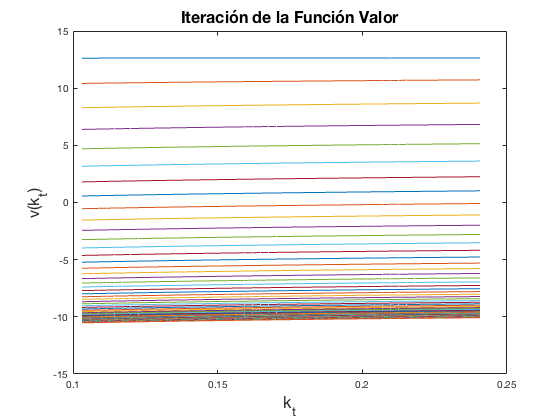

figure;
plot(kgrid,valiter);
title('Iteración de la Función Valor','fontsize',16);
ylabel('v(k_{t})','fontsize',16);
xlabel('k_{t}','fontsize',16);